% For visualisation, the method of visualisation is based upon the youtube tutorial
% called '3D in Matlab for beginners' (https://www.youtube.com/watch?v=NkxRM6VbmW8)
% However, some parts are changed to match with better illustration for
% this task


%Load the tuned-modelplots
load("Random_Forest_HP_tuning")
% Extract the hyper-parameter during the random search 
HP_RF_Parameter = Mdl_HP_RF.HyperparameterOptimizationResults;
x = HP_RF_Parameter.MaxNumSplits

x =         1940
           1
           1
         292
        1940
        4999
        4999
           7
          44
           3


y = HP_RF_Parameter.Objective

y =     0.0586
    0.1644
    0.2192
    0.0568
    0.0562
    0.0568
    0.0882
    0.1162
    0.0722
    0.1538


z = HP_RF_Parameter.NumVariablesToSample

z =     18
     9
    16
    16
    12
     7
     1
     9
     7
     9




% Add Interpolation 
[xx, zz] = meshgrid(x,z)

xx =         1940           1           1         292        1940        4999        4999           7          44           3        4999           3           1           1           3          44         292         292        1940         292         292          44           7         753           1
        1940           1           1         292        1940        4999        4999           7          44           3        4999           3           1           1           3          44         292         292        1940         292         292          44           7         753           1
        1940           1           1         292        1940        4999        4999           7          44           3        4999           3           1           1           3          44         292         292        1940         292         292          44           7         753           1
        1940           1           1         292        1940        4999        4999        

zz =     18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18
     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9
    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16
    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16
    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12
     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     

gd = griddata(x,z,y,xx,zz)

gd =     0.0586    0.2192    0.2192    0.0598    0.0586    0.0598    0.0598    0.1342    0.0658    0.1456    0.0598    0.1456    0.2192    0.2192    0.1456    0.0658    0.0598    0.0598    0.0586    0.0598    0.0598    0.0658    0.1342    0.0601    0.2192
    0.0567    0.1644    0.1644    0.0556    0.0567    0.0574    0.0574    0.1162    0.0692    0.1538    0.0574    0.1538    0.1644    0.1644    0.1538    0.0692    0.0556    0.0556    0.0567    0.0556    0.0556    0.0692    0.1162    0.0570    0.1644
    0.0578    0.2192    0.2192    0.0568    0.0578    0.0593    0.0593    0.1302    0.0655    0.1456    0.0593    0.1456    0.2192    0.2192    0.1456    0.0655    0.0568    0.0568    0.0578    0.0568    0.0568    0.0655    0.1302    0.0580    0.2192
    0.0578    0.2192    0.2192    0.0568    0.0578    0.0593    0.0593    0.1302    0.0655    0.1456    0.0593    0.1456    0.2192    0.2192    0.1456    0.0655    0.0568    0.0568    0.0578    0.0568    0.0568    0.0655    0.1302    0.0580  


% add facealpha to see the visualisation in transparent manner in order to
% clarify each hyper-parameter point
figure
surf(x,z,gd,'FaceAlpha',0.2,'DisplayName','Surface Plot')
colormap(parula) % Specify colour map
colorbar % add colour bar
title('Random Forest Hyperparemeter Results')
xlabel('MaxNumSplits','FontSize',11)
ylabel('NumVariablesToSample','FontSize',11)
zlabel('Objective','FontSize',11)
% Visualise each hyper-parameter during the grid-search
hold on 
plot3(x,z,y,'o','Color','r','MarkerSize',10,'MarkerFaceColor','#ffd9d9','DisplayName','Hyperparameter')
grid on
% Visualise the optimal point based upon the grid-search
hold on 
a = plot3(292,9,0.0556,'o','Color','r','MarkerSize',15,'MarkerFaceColor','#f00707','DisplayName','Global Optima')

a =   Line (Global Optima) のプロパティ:

              Color: [1 0 0]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 15
    MarkerFaceColor: [0.9412 0.0275 0.0275]
              XData: 292
              YData: 9
              ZData: 0.0556

  すべてのプロパティ を表示


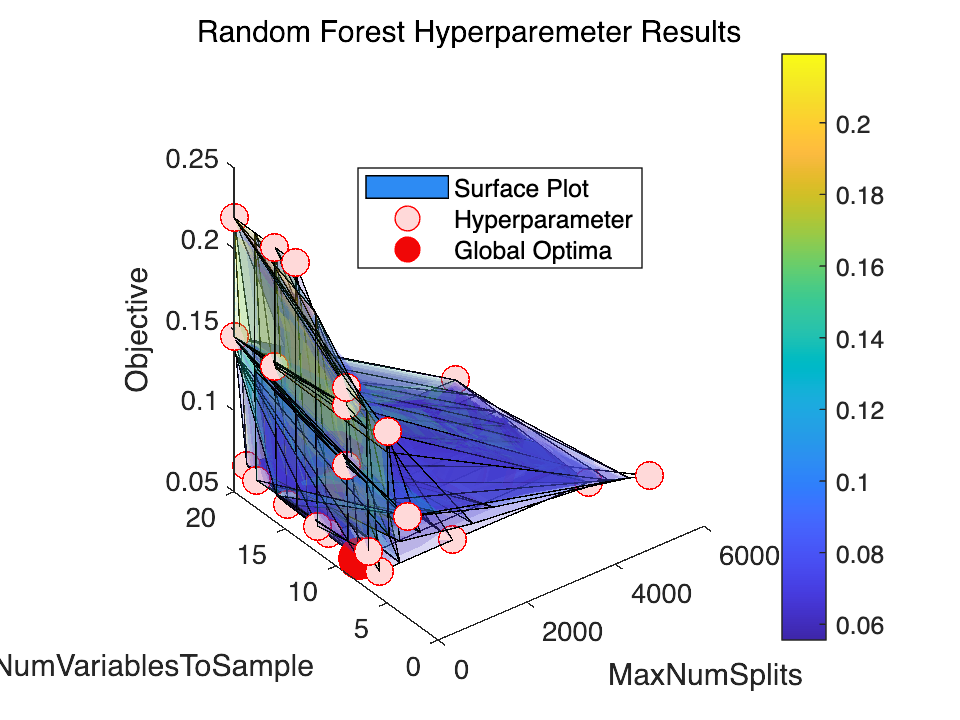

uistack(a,'top') 
legend('Position',[0.39244,0.63723,0.25585,0.1199])
grid Off